clear all; close all; clc;

lc = lines(7);
if ~ exist(fullfile(pwd,'images'),'dir'), mkdir images; end

% lt = @(s) clipboard('copy',latex(s));

% B

syms v_a T_e R L K_e K_t D_1 D_2 J_1 J_2 B

ia      = sym('i_a_',[1,2]);
phi1    = sym('phi_1_',[1,2]);
w1      = sym('omega_1_',[1,2]);
phi2    = sym('phi_2_',[1,2]);
w2      = sym('omega_2_',[1,2]);
phi3    = sym('phi_3_',[1,2]);

x = [phi1; w1; phi2; w2; phi3]

$$x = \left(\begin{array}{cc} \varphi_{1,1} & \varphi_{1,2}\\ \omega_{1,1} & \omega_{1,2}\\ \varphi_{2,1} & \varphi_{2,2}\\ \omega_{2,1} & \omega_{2,2}\\ \varphi_{3,1} & \varphi_{3,2} \end{array}\right)$$

u = [v_a; T_e]

$$u = \left(\begin{array}{c} v_{a}\\ T_{e} \end{array}\right)$$


eqs = [       
        J_1*w1(2) == K_t*((v_a-K_e*w1(1))/(R)) - D_1*(phi1(1)-phi2(1)) ;
        J_2*w2(2) == D_1*(phi1(1)-phi2(1)) - D_2*(phi2(1)-phi3(1)) ;
        0 == D_2*(phi2(1)-phi3(1)) - B*phi3(2) + T_e;
        phi1(2) == w1(1) ;
        phi2(2) == w2(1) 
    ];
     
eqs = lhs(eqs) - rhs(eqs);

[Am,Bm] = get_state_space(eqs, x(:,2), x(:,1), u)

$$Am = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ -\frac{D_{1}}{J_{1}} & -\frac{K_{e}\,K_{t}}{J_{1}\,R} & \frac{D_{1}}{J_{1}} & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ \frac{D_{1}}{J_{2}} & 0 & -\frac{D_{1}+D_{2}}{J_{2}} & 0 & \frac{D_{2}}{J_{2}}\\ 0 & 0 & \frac{D_{2}}{B} & 0 & -\frac{D_{2}}{B} \end{array}\right)$$

$$Bm = \left(\begin{array}{cc} 0 & 0\\ \frac{K_{t}}{J_{1}\,R} & 0\\ 0 & 0\\ 0 & 0\\ 0 & \frac{1}{B} \end{array}\right)$$


% A
vars_sym   = [K_e   , K_t   , J_1   , J_2   , B     , D_2]; 
vars_value = [.1    , .1    , 1e-5  , 4e-5  , 2e-3  ,  2];
repl = @(x) subs(x, vars_sym, vars_value);

C1 = [
    0 0 1 0 0      ;
    0 0 0 1 0
]

C1 =      0     0     1     0     0
     0     0     0     1     0



C2 = [
    0 -K_e/R 0 0 0      ;
    0 0 D_2/B 0 -D_2/B
];

D1 = [
    0 0   ;
    0 0
]

D1 =      0     0
     0     0



D2 = [
    1/R 0   ;
    0   1/B
]

$$D2 = \left(\begin{array}{cc} \frac{1}{R} & 0\\ 0 & \frac{1}{B} \end{array}\right)$$


A = repl(Am)

$$A = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ -100000\,D_{1} & -\frac{1000}{R} & 100000\,D_{1} & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 25000\,D_{1} & 0 & -25000\,D_{1}-50000 & 0 & 50000\\ 0 & 0 & 1000 & 0 & -1000 \end{array}\right)$$

B = repl(Bm);

C1 = repl(C1);
D1 = repl(D1)

$$D1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0 \end{array}\right)$$


C2 = repl(C2);
D2 = repl(D2);

vars_sym   =  [D_1]; 
vars_value =  [20];
repl = @(x) subs(x, vars_sym, vars_value);
A = repl(A)

$$A = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ -2000000 & -\frac{1000}{R} & 2000000 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 500000 & 0 & -550000 & 0 & 50000\\ 0 & 0 & 1000 & 0 & -1000 \end{array}\right)$$


det(A)

$$ans = 0$$

% Symbolic variable for R

% Calculate the characteristic polynomial
characteristic_poly = det(A - eye(size(A)) * sym('lambda'))

$$characteristic\_poly = -\frac{500000000000\,\lambda +100000000000\,R\,\lambda +2500000000\,R\,\lambda^{2}+2550000\,R\,\lambda^{3}+1000\,R\,\lambda^{4}+R\,\lambda^{5}+550000000\,\lambda^{2}+1000000\,\lambda^{3}+1000\,\lambda^{4}}{R}$$

    

% Solve for the values of R when the real part of any eigenvalue becomes positive
unstable_R_values = solve(characteristic_poly == 0 , R) 

$$unstable\_R\_values = -\frac{1000\,\lambda^{3}+1000000\,\lambda^{2}+550000000\,\lambda +500000000000}{\lambda^{4}+1000\,\lambda^{3}+2550000\,\lambda^{2}+2500000000\,\lambda +100000000000}$$


% Display the critical values of R for instability
disp('Critical values of R for instability:');

Critical values of R for instability:


disp(unstable_R_values)

$$-\frac{1000\,\lambda^{3}+1000000\,\lambda^{2}+550000000\,\lambda +500000000000}{\lambda^{4}+1000\,\lambda^{3}+2550000\,\lambda^{2}+2500000000\,\lambda +100000000000}$$








disp("Not MATLAB functions")

Not MATLAB functions


% S matrix
disp("S matrix rank")

S matrix rank


s = [B A*B A^2*B A^3*B A^4*B]

$$s = \begin{array}{l} \left(\begin{array}{cccccccccc} 0 & 0 & \frac{10000}{R} & 0 & \sigma_{2} & 0 & \frac{10000\,\sigma_{4}}{R} & 0 & \sigma_{3} & 50000000000000\\ \frac{10000}{R} & 0 & \sigma_{2} & 0 & \frac{10000\,\sigma_{4}}{R} & 0 & \sigma_{3} & 50000000000000 & \frac{10000\,\left({\sigma_{4}}^{2}-\frac{2000000000000}{R^{2}}+1000000000000\right)}{R} & -\frac{50000000000000000}{R}-50000000000000000\\ 0 & 0 & 0 & 0 & 0 & 25000000 & \frac{5000000000}{R} & -25000000000 & \sigma_{1} & 11250000000000\\ 0 & 0 & 0 & 25000000 & \frac{5000000000}{R} & -25000000000 & \sigma_{1} & 11250000000000 & \frac{10000\,\left(\frac{500000000000}{R^{2}}-1275000000000\right)}{R} & -10000000000000000\\ 0 & 500 & 0 & -500000 & 0 & 500000000 & 0 & -475000000000 & \frac{5000000000000}{R} & 450000000000000 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{5000000000000}{R^{2}}\\ \sigma_{2}=-\frac{10000000}{R^{2}}\\ \sigma_{3}=-\frac{10000\,\left(\frac{1000\,\sigma_{4}}{R}-\frac{2000000000}{R}\right)}{R}\\ \sigma_{4}=\frac{1000000}{R^{2}}-2000000 \end{array}$$

rank(s)

ans = 5

rref(s);
% Controllable

% C matrix case 1
disp("o_case_1")

o_case_1


o = [C1; C1*A; C1*A^2; C1*A^3; C1*A^4]

$$o = \left(\begin{array}{ccccc} 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 & 0\\ 500000 & 0 & -550000 & 0 & 50000\\ 500000 & 0 & -550000 & 0 & 50000\\ 0 & 500000 & 50000000 & -550000 & -50000000\\ 0 & 500000 & 50000000 & -550000 & -50000000\\ -1275000000000 & -\frac{500000000}{R} & 1252500000000 & 50000000 & 22500000000\\ -1275000000000 & -\frac{500000000}{R} & 1252500000000 & 50000000 & 22500000000\\ \frac{1000000000000000}{R}+25000000000000 & \frac{500000000000}{R^{2}}-1275000000000 & -\frac{1000000000000000}{R}-5000000000000 & 1252500000000 & -20000000000000 \end{array}\right)$$

size(o)

ans =     10     5


rank(o)

ans = 5

rref(o)

$$ans = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

% Observable

% C matrix case 2
disp("o_case_2")

o_case_2


o = [C2; C2*A; C2*A^2; C2*A^3; C2*A^4]

$$o = \begin{array}{l} \left(\begin{array}{ccccc} 0 & -\frac{1}{10\,R} & 0 & 0 & 0\\ 0 & 0 & 1000 & 0 & -1000\\ \frac{200000}{R} & \frac{100}{R^{2}} & -\frac{200000}{R} & 0 & 0\\ 0 & 0 & -1000000 & 1000 & 1000000\\ -\frac{200000000}{R^{2}} & -\frac{\sigma_{1}}{10\,R} & \frac{200000000}{R^{2}} & -\frac{200000}{R} & 0\\ 500000000 & 0 & 450000000 & -1000000 & -950000000\\ \frac{\frac{2000000000000}{R^{2}}-5000000000000}{10\,R} & \frac{\frac{1000\,\sigma_{1}}{R}-\frac{2000000000}{R}}{10\,R} & \sigma_{2} & \frac{200000000}{R^{2}} & -\frac{10000000000}{R}\\ -500000000000 & 500000000 & -400000000000 & 450000000 & 900000000000\\ -\frac{\frac{2000000000\,\sigma_{1}}{R}-\frac{5000000000000000}{R}}{10\,R} & -\frac{{\sigma_{1}}^{2}-\frac{2000000000000}{R^{2}}+1000000000000}{10\,R} & -\frac{\frac{5100000000000000}{R}-\frac{2000000000\,\sigma_{1}}{R}+100000000000000}{10\,R} & \sigma_{2} & \frac{\frac{100000000000000}{R}+100000000000000}{10\,R}\\ -775000000000000 & -\frac{500000000000}{R}-500000000000 & 1652500000000000 & -400000000000 & -877500000000000 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{1000000}{R^{2}}-2000000\\ \sigma_{2}=-\frac{\frac{2000000000000}{R^{2}}-5100000000000}{10\,R} \end{array}$$

size(o)

ans =     10     5


rank(o)

ans = 4

rref(o)

$$ans = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & -1\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & -1\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

% Not oObservable

% Question B
% Case 1
% Controllable -> stabilizable
% Observable -> detectable

% Case 2
% Controllable -> stabilizable
% Not Observable -> detectable?

% Question C
% S matrix
syms R K_e K_t J_1 J_2 B D_1 D_2;

vars_sym   = [R, K_e, K_t, J_1, J_2, B, D_1, D_2]; 
vars_value = [1, .1, .1, 1e-5, 4e-5, 2e-3, 20, 2];
repl = @(x) double(subs(x, vars_sym, vars_value));

A = repl(Am)

A =            0           1           0           0           0
    -2000000       -1000     2000000           0           0
           0           0           0           1           0
      500000           0     -550000           0       50000
           0           0        1000           0       -1000


B = repl(Bm);

C1 = repl(C1);
D1 = repl(D1);

C2 = repl(C2);
D2 = repl(D2);

disp("Matlab functions")

Matlab functions



S = ctrb(A,B);
disp("S matrix rank")

S matrix rank


rank(S)

ans = 4

cond(S)

ans = 1.0198e+15


disp("o_case_1")

o_case_1


o_case_1 = obsv(A,C1);
rank(o_case_1)

ans = 4

cond(o_case_1)

ans = 3.1204e+15


disp("o_case_2")

o_case_2


o_case_2 = obsv(A,C2);
rank(o_case_2)

ans = 4

cond(o_case_2)

ans = 1.3703e+16


% Because of the high values in the condition numbers, the system is very
% senstive to the changes, therefor the system is basically unstable

% Question D
Ts = 0.001;
Ad = expm(A*Ts)

Ad =     0.4010    0.0004    0.5964    0.0002    0.0026
 -782.8328   -0.0489  773.7475    0.5964    9.0853
    0.2076    0.0001    0.7749    0.0009    0.0175
  342.5299    0.1491 -370.9589    0.7749   28.4290
    0.0585    0.0000    0.5686    0.0004    0.3729



fun = @(t) expm(A*t);

% Question E
syms s t
matrix = inv(eye(size(A))*s-A);
exp_At = vpa(ilaplace(matrix));

Bd = int(exp_At,t,0,1e-3)*B

$$Bd = \left(\begin{array}{cc} 0.0031544013140411673596222153170599 & 0.00028574261006628368479954993055615\\ 4.4993079133951651484906657908775 & 1.3087884151207141057691325018425\\ 0.00015945310251869977905686824323989 & 0.0032114625105192109575384597973703\\ 0.5851439800905854545477819733629 & 8.7634392335488652045382718738465\\ 0.000028574261006628368479954993055629 & 0.31675856020308770695639115036107 \end{array}\right)$$

% Bd = round(Bd, 8)
Bd = double(Bd)

Bd =     0.0032    0.0003
    4.4993    1.3088
    0.0002    0.0032
    0.5851    8.7634
    0.0000    0.3168












% Question F

disp("eif of Ad ")

eif of Ad 


eig(Ad)

ans =    0.0619 + 0.6733i
   0.0619 - 0.6733i
   1.0000 + 0.0000i
   0.7627 + 0.0000i
   0.3881 + 0.0000i



DT_cont = ctrb(Ad,Bd);
DT_obsv = obsv(Ad,C2);

rref(transpose(DT_cont))

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


rref(DT_obsv)

ans =     1.0000         0         0         0   -1.0000
         0    1.0000         0         0         0
         0         0    1.0000         0   -1.0000
         0         0         0    1.0000   -0.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0



rank(DT_cont)

ans = 5

rank(DT_obsv)

ans = 4

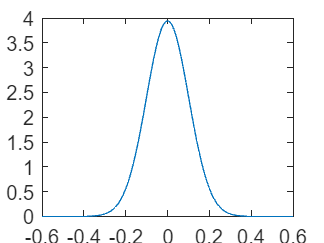


%System 1 is controlable and observebility
% The system is stabel if the eid is less then 1. In this system there is
% at least one eigen value withch do not satisfy the criteria. not minimal
% realization becouse 

%system 2 is controlable but not observebility
% The system is stabel if the eid is less then 1. In this system there is
% at least one eigen value withch do not satisfy 
% the criteria. not minimal
% realization becouse it is not observebility 



% Project 3
Ts = 1e-3;

% A 
sigma2_va   = calcVariance(0.3, 0.997);

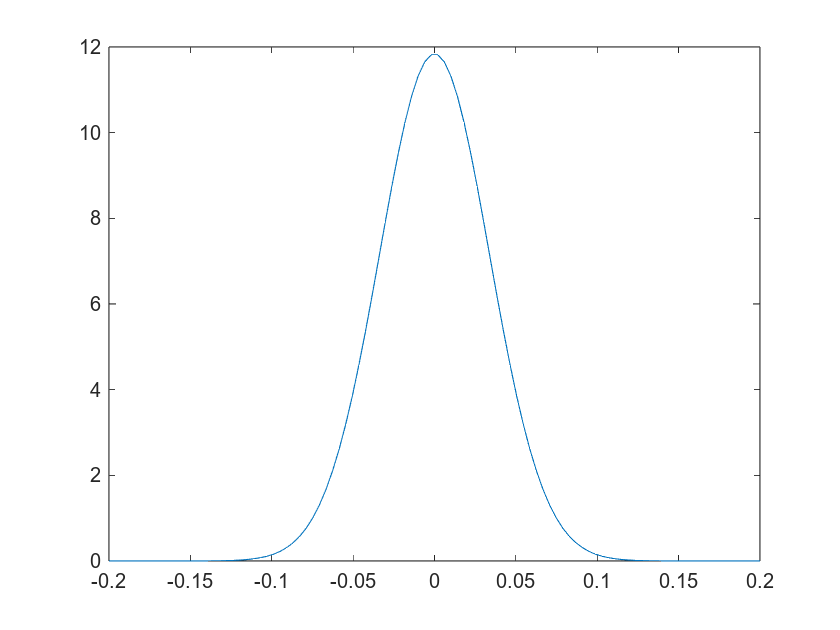

sigma2_Te   = calcVariance(0.1, 0.997);

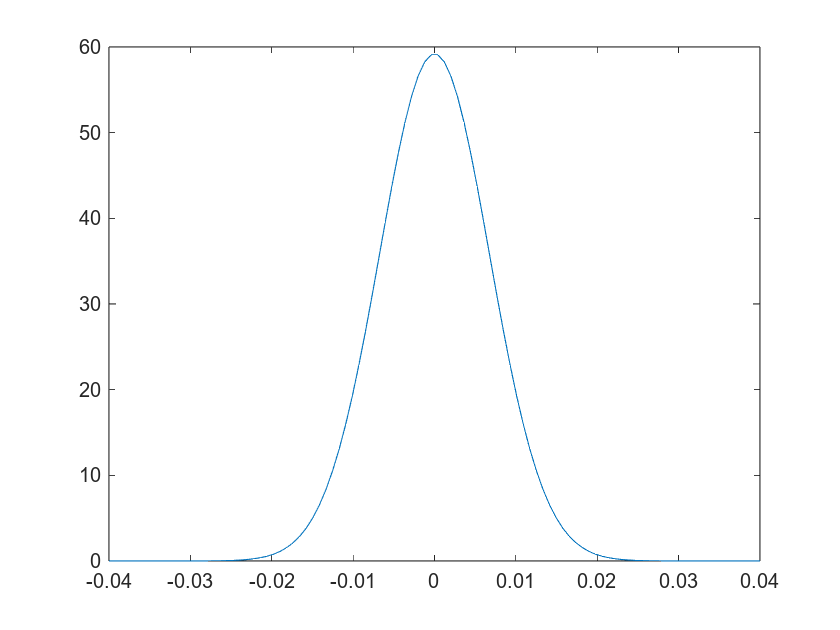

sigma2_phi2 = calcVariance(0.02, 0.997);

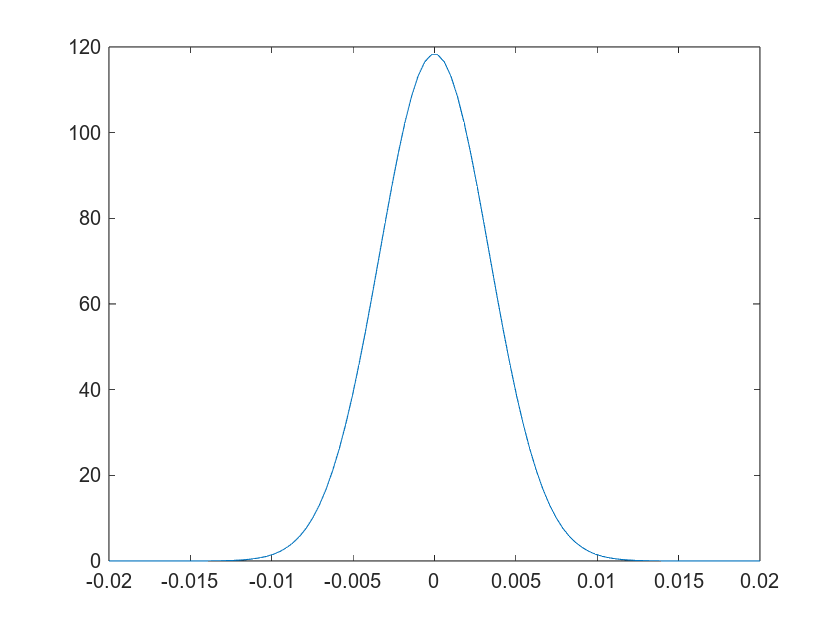

sigma2_w2   = calcVariance(0.01, 0.997);


R = diag([sigma2_va sigma2_Te sigma2_phi2 sigma2_w2]);  

% B 
Qm_kalman = diag([sigma2_va,0,0,sigma2_Te,0]);
Rm_kalman = diag([sigma2_phi2, sigma2_w2]);
sys = ss(A,B,C1,0);


% Kf = lqe(Ad',C1',Qm,Rm);
% SYS_kalman= ss(Ad-Kf*C1,[Bd Kf],C1,0)
% % disc_sys_case2 = ss(Ad,[Bd Bd],C2,0)
% 
% % Kalman case 1sss

% Qm = diag([sigma2_va, sigma2_Te]);
% Rm = diag([sigma2_phi2, sigma2_w2]);
% [k1,S,P] = lqr(disc_sys_case1,Qm,Rm)
% k1
% format long
% disp(P)
% eig(Ad - k1*C1)
% % kalman case 2

% does not work becouse of the sysem is unstable 

Qm = diag([0 0 0 1 0]);
Rm = diag([1 1]);
[k_lq   , S, P] = lqr(sys, Qm, Rm)

k_lq =     5.0043    0.0029   -5.4068    0.0097    0.4025
  138.4359    0.0201 -150.5477    0.9765   12.1119


S =     3.4029    0.0005   -3.6797    0.0212    0.2769
    0.0005    0.0000   -0.0005    0.0000    0.0000
   -3.6797   -0.0005    3.9808   -0.0231   -0.3011
    0.0212    0.0000   -0.0231    0.0003    0.0020
    0.2769    0.0000   -0.3011    0.0020    0.0242


P = 1.0e+03 *

  -0.0000 + 0.0000i
  -0.5160 + 1.3223i
  -0.5160 - 1.3223i
  -3.5267 + 3.5363i
  -3.5267 - 3.5363i


%   
% eig(Ad- k2*C1)
A

A =            0           1           0           0           0
    -2000000       -1000     2000000           0           0
           0           0           0           1           0
      500000           0     -550000           0       50000
           0           0        1000           0       -1000



new_k = [k_lq(1,3) k_lq(2,4)]

new_k =    -5.4068    0.9765


C_lq = [0 0 1 1 0]

C_lq =      0     0     1     1     0



A_lq= [A zeros(5,1);
      C_lq 0]

A_lq =            0           1           0           0           0           0
    -2000000       -1000     2000000           0           0           0
           0           0           0           1           0           0
      500000           0     -550000           0       50000           0
           0           0        1000           0       -1000           0
           0           0           1           1           0           0



B_lq = [B;
        zeros(1,2)] 

B_lq =            0           0
       10000           0
           0           0
           0           0
           0         500
           0           0


% % new_sys = ss(A_lq,B_lq,[C1 zeros(2,2)],0) 

Qm_lqi= diag([1 1 1 100 1 10]);
Rm_lqi = diag([1 1]);
K_lqi = lqr(A_lq,B_lq,Qm_lqi,Rm_lqi)

K_lqi =     3.4843    0.9052   -3.3193    0.0298    0.3104    0.2934
  428.6448    0.0155 -465.8090    9.9802   42.7319    3.1486



newK = K_lqi(:,1:5)

newK =     3.4843    0.9052   -3.3193    0.0298    0.3104
  428.6448    0.0155 -465.8090    9.9802   42.7319


newKi = K_lqi(:,6:6)'

newKi =     0.2934    3.1486


function [A,b] = get_state_space(eqs, xdot, x, u)
    A = -jacobian(eqs, xdot) \ jacobian(eqs, x);
    b = -jacobian(eqs, xdot) \ jacobian(eqs, u);
end


function sigma2_val = calcVariance(ub, realization_ub)
    syms sigma2 x
    eq = realization_ub == int(1/sqrt(2*pi*sigma2)*exp(-(x^2)/(2*sigma2)),x,-ub,ub);
    sigma2_val = double(solve(eq,sigma2));
    mu = 0;
    pd = makedist('Normal',mu,abs( sqrt(sigma2_val)));
    v_aw = linspace(-ub*2,ub*2,100);
    y = pdf(pd,v_aw);
    figure('Color','white');
    plot(v_aw,y)
end